Ap = 0.07;
Aa = 50;
Wp1 = 600;
Wp2 = 1000;
Wa1 = 450;
Wa2 = 1100;
Ws = 3000;
T = 2*pi/Ws ;
X = -100:100;
Bt = min([(Wp1-Wa1),(Wa2-Wp2)]);
Wc1 = Wp1 - Bt/2;
Wc2 = Wp2 + Bt/2;

%calculating delta
deltap = (10^(0.05*Ap)-1)/(10^(0.05*Ap)+1) ;
deltaa = 10^-(0.05*Aa) ;
delta = min([deltap,deltaa]);

%calculating actual stopband attenution
Aa1 = -20*log10(delta);
%calculating alpha
if Aa1<= 21
 alpha = 0;
elseif Aa1>50
 alpha = 0.1102*(Aa1-8.7);
else
 alpha = 0.5842*((Aa1-21)^0.4) + 0.07886*(Aa1-21);
end

%calculating value of D
if Aa1<=21
 D= 0.9222;
else
 D = (Aa1-7.95)/14.36;
end

%calculating value of N
if mod(round(1+(Ws*D)/Bt),2)==0
 N = round(1+(Ws*D)/Bt)+1;
else
 N = round(1+(Ws*D)/Bt);
end
lim_N=(N-1)/2;
len_filter=-lim_N:1:lim_N;

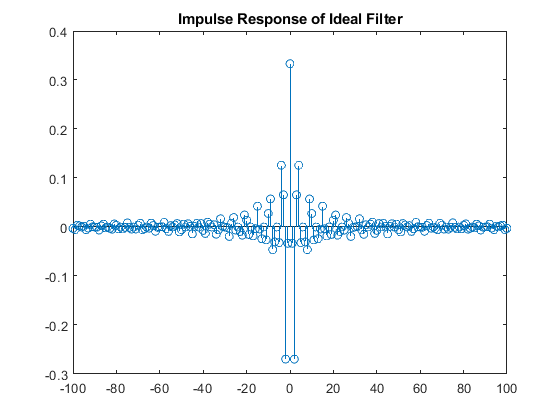

%plotting impulse response
figure
[hnT] = ideal(X,Wc2,Wc1,Ws,T);
stem(X,hnT)
title('Impulse Response of Ideal Filter')

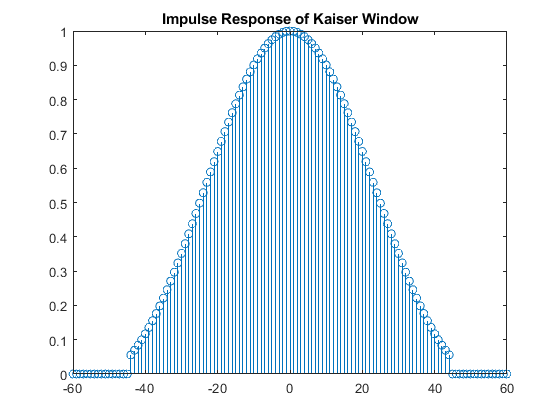

%plotting kaiser window impulse response
figure
[WknT] = kwindow(X,alpha,N);
stem(X,WknT)
xlim([-60,60]);
title('Impulse Response of Kaiser Window')

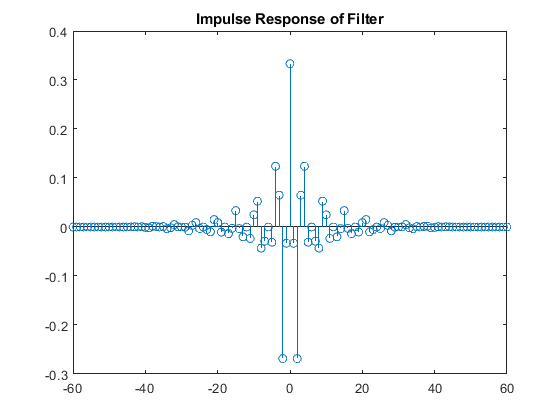

%plotting filter function
figure
hn = hnT.*WknT;
stem(X,hn)
xlim([-60,60]);
title('Impulse Response of Filter')

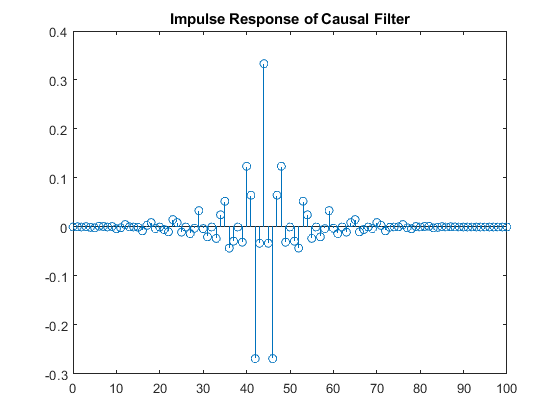

%plotting causal impulse response
bp = zeros(size(hn));
for k1 = 1:length(hn)-((N-1)/2)
    bp(k1+(N-1)/2)= hn(k1);
end
figure
stem(X,bp)
xlim([0,100]);
title('Impulse Response of Causal Filter')

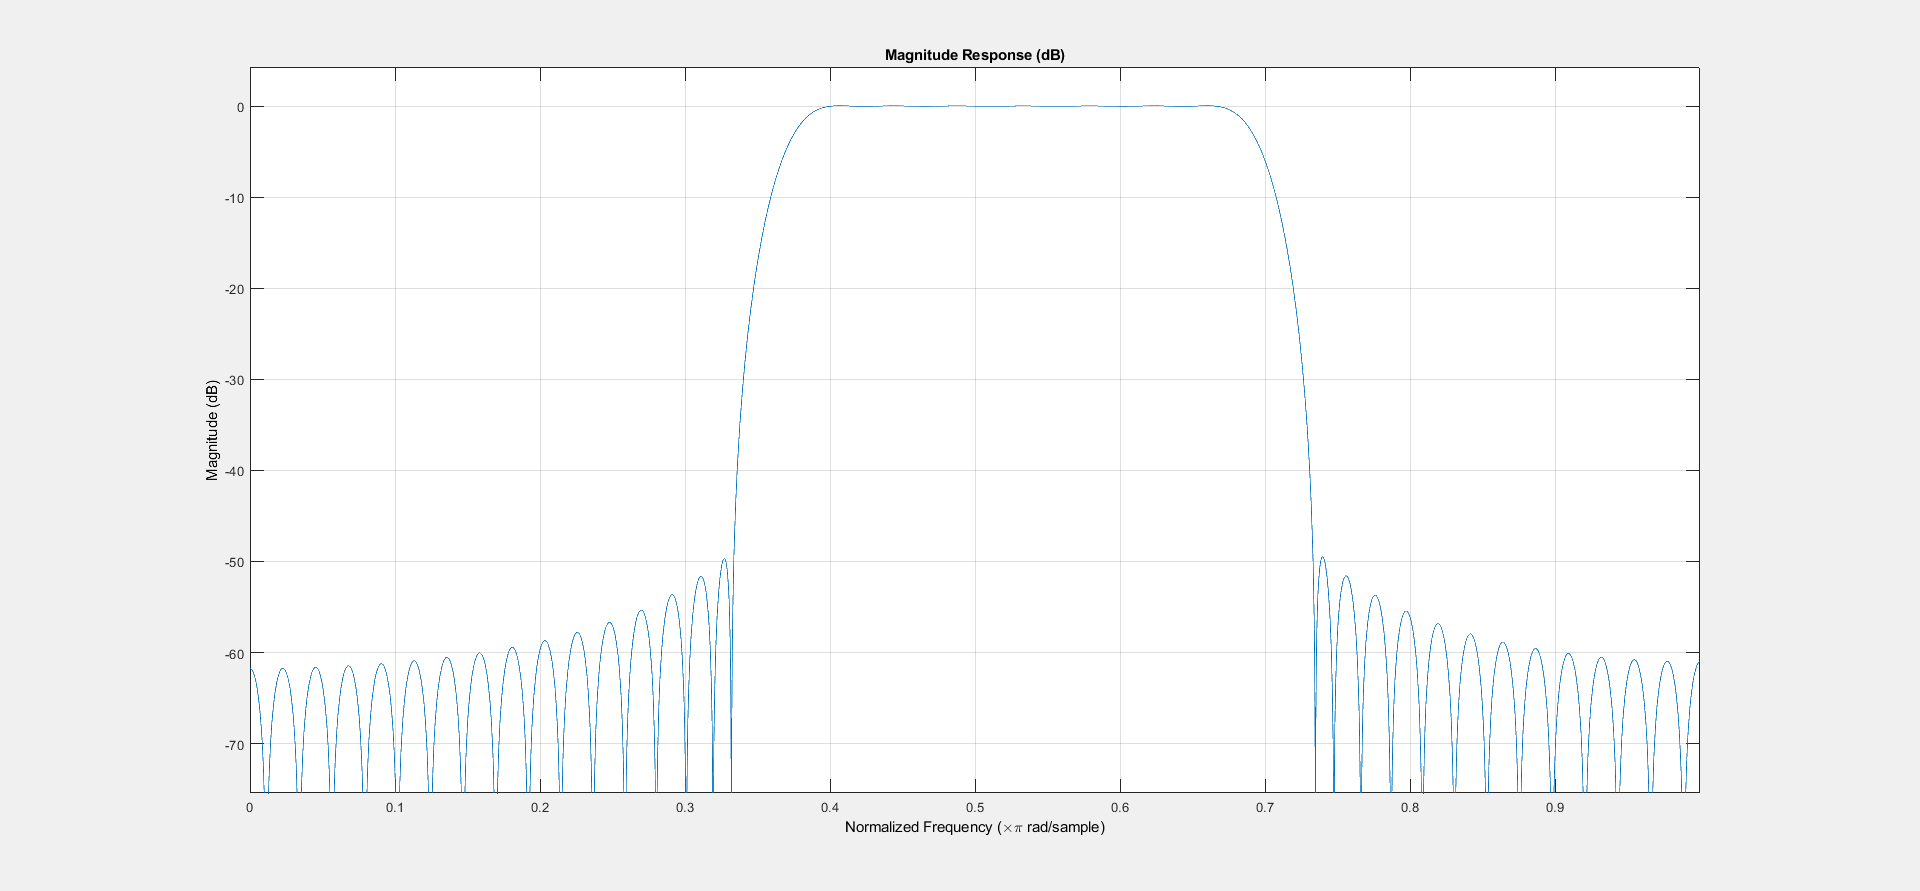

%plotting the magnitude response of the filter
fvtool(hn);

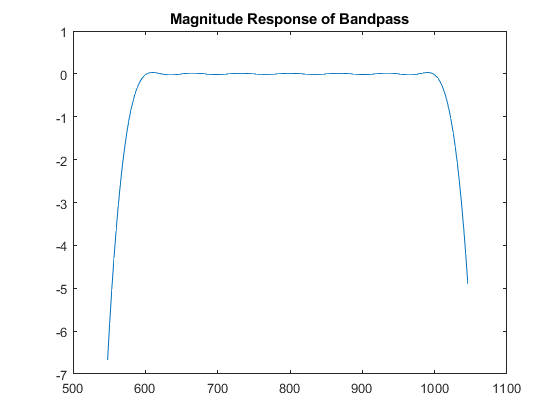

[h,w]=freqz(hn);
w=w/T;
h=20*log10(abs(h));
lim_low=round(length(w)/(Ws/2)*Wc1);
lim_upp=round(length(w)/(Ws/2)*Wc2);
plot(w(lim_low:lim_upp),h(lim_low:lim_upp))
title('Magnitude Response of Bandpass')

o1=Wa1/2;
o2=(Wp1+Wp2)/2;
o3=(Wa2+Ws/2)/2;
samples=500;
nT=0:T:samples*T;
len_fft = 2^nextpow2(samples);
frequency = Ws*(0:1/len_fft:1/2);
x_nt=sin(o1*nT)+sin(o2*nT)+sin(o3*nT);
Xw = fft(x_nt,len_fft);
X1 = T*abs(Xw(1:len_fft/2+1));
Hw = fft(hn,len_fft);
Yw=Hw.*Xw;
y_nt=ifft(Yw,len_fft);
Y = T*abs(Yw(1:len_fft/2+1));
y_ideal=sin(o2*nT);
Yw_ideal=fft(y_ideal,len_fft);
Y_ideal= T*abs(Yw_ideal(1:len_fft/2+1));

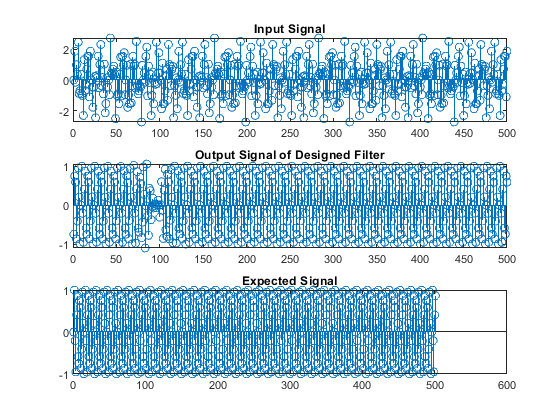

figure,
subplot(3,1,1);
t=(1:samples+1);
stem(t,x_nt(t));
title('Input Signal')
xlim([0,samples]);
subplot(3,1,2);
stem(t,y_nt(t));
title('Output Signal of Designed Filter')
xlim([0,samples]);
subplot(3,1,3);
stem(t,y_ideal(t));
title('Expected Signal')

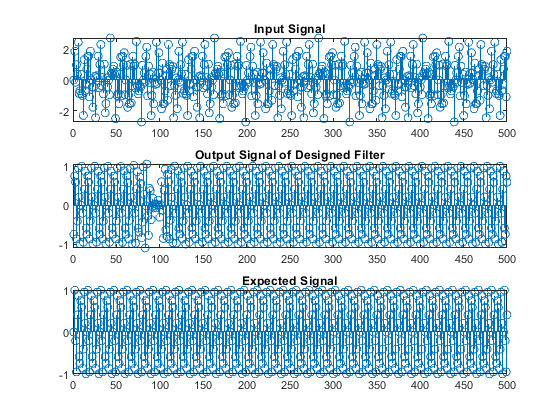

xlim([0,samples]);

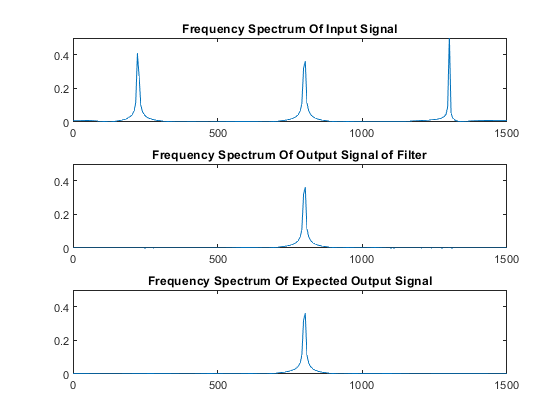

figure, 
subplot(3, 1, 1) ;
plot(frequency,X1);
title('Frequency Spectrum Of Input Signal');
axis([0, 1500, 0, 0.5]);
subplot(3, 1, 2);
plot(frequency, abs(Y'));
title('Frequency Spectrum Of Output Signal of Filter');
axis([0, 1500, 0, 0.5]);
subplot(3, 1, 3);
plot(frequency, abs(Y_ideal'));
title('Frequency Spectrum Of Expected Output Signal');
axis([0, 1500, 0, 0.5]);

Functions

function [h] = ideal(X,Wc2,Wc1,Ws,T) %function for impulse response
    h = zeros(size(X));
    for n = X
        idx = X==n;
        if n == 0
            h(idx) = 2*(Wc2-Wc1)/Ws;
        else
            h(idx) = (1/(n*pi))*(sin(Wc2*n*T)-sin(Wc1*n*T));
        end
    end
end 

%===============================================================

function [Wk] = kwindow(X,alpha,N) %function for kaiser window approximation
    Wk = zeros(size(X));
    beta=alpha*sqrt(1-(2*X/(N-1)).^2);
    for n = X
        idx = X==n;
        if abs(n)<= (N-1)/2
            Wk(idx) = bslfun(beta(idx))/bslfun(alpha);
        else
            Wk(idx) = 0 ;
        end
    end
end

%================================================================

function [I] = bslfun(x) %bessel function
    I = 1;
    for k= 1: 50
        I1 = ((1/factorial(k))*(x/2)^k)^2;
        I = I + I1;
    end
end